# Objective Functions

### Description

Objective functions evaluate an input and return a score that establishes how good the input is. Examples of where objective functions are used:

- Cost functions (used everywhere): evaluate the cost of a given problem solution,

- Loss functions (used in deep learning): evaluate how incorrect an answer is,

- Fitness functions (used by genetic algorithms): the inverse to cost functions.

### Mean Squared error:

The mean squared error function:


$$MSE = \frac{1}{n}\sum\limits_{i=1}^n(Y_i - \hat{Y}_i)^2
$$


calculates the average squared error between $n
$ pairs of true values ($Y$) and estimates of the true values ($\hat{Y}$). The error value will always be positive and due to the squaring of the error signal is significantly more influenced by large errors than by small errors.

MSE = @(preds, labels) mean((preds-labels).^2);

y = [0.8, 0.9]; % true values

% first guess
x1 = [0.15, 0.85];
error = MSE(x1, y)

error = 0.2125


% second guess
x2 = [0.15, 0.9];
error = MSE(x2, y) % note, 0.05 change in x2 has small impact

error = 0.2113


% third guess
x3 = [0.2, 0.85];
error = MSE(x3, y) % note, 0.05 change in x1 has large impact

error = 0.1813

The mean squared error function is used commonly as a cost function and as a loss function. This is due to the fact that any changes proportional to the error will rapidly reduce larger error causes and have a small impact on small error causes.

x_1 = 0.15;

error = MSE([x_1, 0.85], y) % minimum error at x_1 = 0.85, due to error in x_2

error = 0.2125

### **Rastrigin:**

In mathematical optimisation problems the objective is generally to find global minima or maxima of some function. The Rastrigin function is frequently used as a benchmark as it is highly oscillatory lots of local minima and maxima. The Rastrigin function applied to an $n
$ dimensional domain:


$$f(\mathbf{x}) = An + \sum\limits_{i=1}^n[x_i^2 - A\cos(2\pi x_i)]$$


In one and two dimensions this becomes:


$$f(x) = A + [x^2 - A\cos(2\pi x)]$$



$$f(\mathbf{x}) = 2A + [x_1^2 - A\cos(2\pi x_1)] + [ x_2^2 - A\cos(2\pi x_2)]$$


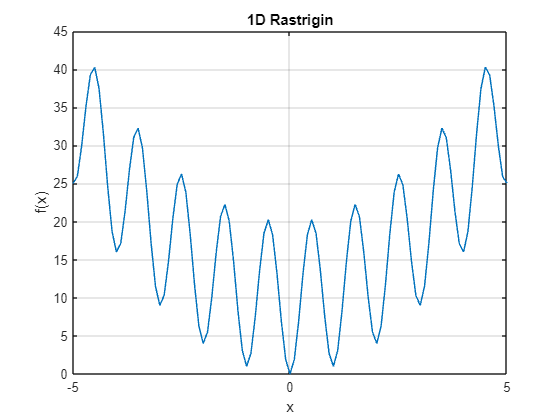

% 1D
rastrigin_1d = @(x) 10 + (x.^2 - 10.*cos(2*pi.*x)); 

x = -5:0.1:5;
plot(x, rastrigin_1d(x))
xlabel("x")
ylabel("f(x)")
title("1D Rastrigin")
grid()

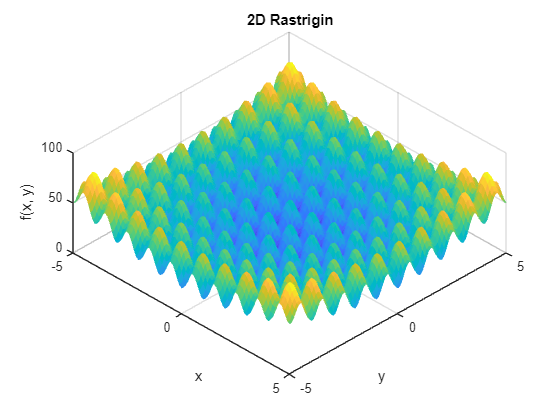

% 2D
rastrigin_2d = @(x, y) 20 + (x.^2 - 10.*cos(2*pi.*x)) + (y.^2 - 10.*cos(2*pi.*y));

x = -5:0.1:5;
y = -5:0.1:5;

[X,Y] = meshgrid(x, y);
Z = rastrigin_2d(X, Y);

surf(X, Y, Z, EdgeAlpha=0)
view(45, 60)
xlabel("x")
ylabel("y")
zlabel("f(x, y)")
title("2D Rastrigin")

### **Binary Cross Entropy**

The Binary Cross Entropy (BCE) function is commonly used in machine learning when the machine learning model is outputting probabilities, that an item belongs to one of two discrete categories. The binary Cross Entropy function:


$$f(\mathbf{Y}, \hat{\mathbf{Y}}) = -\frac{1}{n}\sum\limits_{i=1}^n \hat{Y}_i\log(Y) + (1-\hat{Y})\log(1-Y_i)
$$


takes as input two vectors ($\mathbf{Y} \text{ and } \hat{\mathbf{Y}}$) of probabilities. The i'th entry of vector $\mathbf{Y}$ is the predicted probability that the i'th item belongs the first category. The i'th entry of vector $\hat{\mathbf{Y}}$ (often called "label") is the true probability that the i'th item belongs the first category.  Consider the following table of items that can either be a cat (assigned label "0") or a dog (assigned label "1"):


$$\matrix{
\text{item} & \text{label}    	& \hat{\mathbf{Y}} 	& \mathbf{Y}   \cr
1		& \text {cat}      & 0 			& 			0.50  \cr
2		& \text {dog}     & 1 			&			0. 92 \cr
3	        & \text {dog}     & 1 			&		        0. 81 \cr
4	        & \text {cat}      & 0 			& 		  	0.85  \cr
5	        & \text {dog}     & 1 			& 		  	0.65  \cr
}$$


The model has predicted a probability of 0.5 that item 1 is a dog, as such the model is entirely uncertain regarding the identity of item 1. Items 2 and 3 are dogs,  the model has predicted probabilities of 0.92 and 0.81 that items 2 and 3 are dogs, these are fairly good predictions. Item 4 is a cat but the model has predicted a probability of 0.85 that item 4 is a dog, as such this is a very poor prediction. The BCE function can be used to quantify how good (called "loss" in machine learning) these predictions are.

BCE = @(preds, labels) -mean(labels.*log(preds) + (1-labels).*log(1-preds));

labels = [0, 1, 1, 0, 1]; % note this is categorical data, but not one hot encoded

%first set of predictions
preds1 = [0.5, 0.92, 0.81, 0.85, 0.65];
loss = BCE(preds1, labels)

loss = 0.6630


% second set with fourth prediction adjusted
preds2 = [0.5, 0.92, 0.81, 0.2, 0.65];
loss = BCE(preds2, labels)

loss = 0.3282

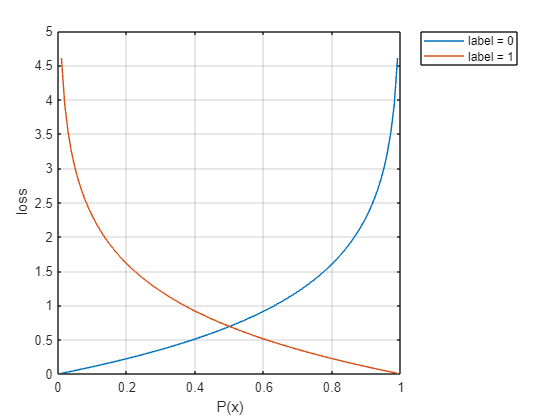



% plotting the loss for different values of the prediction
p = linspace(0.01, 0.99, 101);

plot(p, BCE(p, zeros(101, 1)))  % label = 0
hold on 
plot(p, BCE(p, ones(101, 1))) % label = 1
xlabel("P(x)")
ylabel("loss")
legend(["label = 0", "label = 1"])
grid()

Note asymptotic at P(x) = 0 and P(x) = 1. Hence the predicted probability should never be exactly 0 or 1.

### **Categorical Cross Entropy**

The Categorical Cross Entropy (CCE) extends the idea of the BCE function to cases where the data items can belong to $m
$ discrete categories:


$$f(\mathbf{Y}, \hat{\mathbf{Y}}) = -\frac{1}{n}\sum\limits_{i=1}^n \sum\limits_{j=1}^m\hat{Y}_{ij}\log(Y_{ij})
$$


here $\mathbf{Y}, \hat\mathbf{Y} \in \mathbb{R}^{n\times m}$ are one hot encoded matrices, where $\mathbf{Y}_{ij}$ is the predicted probability that the i'th item belongs to category $j$. Similarly, $\hat\mathbf{Y}_{ij}$ is the true probability of the i'th item belonging to the j'th category. Consider the following data:


$$\matrix{
\text{item} & \text{label}    	& \hat{\mathbf{Y}} 	& \mathbf{Y}   \cr
1		& \text {apple}        & [1,\ 0,\ 0] 			& 			[0.50,\ 0.25,\ 0.25]  \cr
2		& \text {orange}     &  [0,\ 1,\ 0] 			&			[0.05,\ 0.90,\ 0.05] \cr
3	        & \text {pear}         &  [0,\ 0,\ 1] 			&		        [0.20,\ 0.05,\ 0.75] \cr
4	        & \text {apple}       &  [1,\ 0,\ 0] 			& 		  	[0.80,\ 0.02,\ 0.18]  \cr
5	        & \text {orange}     & [0,\ 1,\ 0]			& 		  	[0.04,\ 0.95,\ 0.01]  \cr
}$$


CCE = @(preds, labels) -mean(sum(labels.*log(preds), 2));

labels = categorical(["apple"; "orange"; "pear"; "apple"; "orange"]);
labels = onehotencode(labels, 2) % one hot encode 

labels =      1     0     0
     0     1     0
     0     0     1
     1     0     0
     0     1     0



preds = [0.5, 0.25, 0.25;
        0.05, 0.9, 0.05;
        0.2, 0.05, 0.75;
        0.8, 0.02, 0.18;
        0.04, 0.95, 0.01];

loss = CCE(preds, labels)

loss = 0.2721